h = 0.5;
A = 750000;
i = 0;
aprox = zeros(1,62);
r = 0.05;
time = 0;
while A > 0
    aprox(i+1) = A;
    ap = r * A - 12 * 4000;
    A = A + h * ap;
    i = i + 1;
    time = time + h;
end
aprox(i+1) = A

aprox = 	1.0e+05 *

    7.5000    7.4475    7.3937    7.3385    7.2820    7.2240    7.1646    7.1038    7.0414    6.9774    6.9118    6.8446    6.7757    6.7051    6.6328    6.5586    6.4825    6.4046    6.3247    6.2428    6.1589    6.0729    5.9847    5.8943    5.8017    5.7067    5.6094    5.5096    5.4074    5.3025    5.1951    5.0850    4.9721    4.8564    4.7378    4.6163    4.4917    4.3640    4.2331    4.0989    3.9614    3.8204    3.6759    3.5278    3.3760    3.2204    3.0609    2.8974    2.7299    2.5581


aprox = 	1.0e+05 *

    7.5000    7.4475    7.3937    7.3385    7.2820    7.2240    7.1646    7.1038    7.0414    6.9774    6.9118    6.8446    6.7757    6.7051    6.6328    6.5586    6.4825    6.4046    6.3247    6.2428    6.1589    6.0729    5.9847    5.8943    5.8017    5.7067    5.6094    5.5096    5.4074    5.3025    5.1951    5.0850    4.9721    4.8564    4.7378    4.6163    4.4917    4.3640    4.2331    4.0989    3.9614    3.8204    3.6759    3.5278    3.3760    3.2204    3.0609    2.8974    2.7299    2.5581


A

A = -1.0731e+04

i

i = 62

time

time = 31

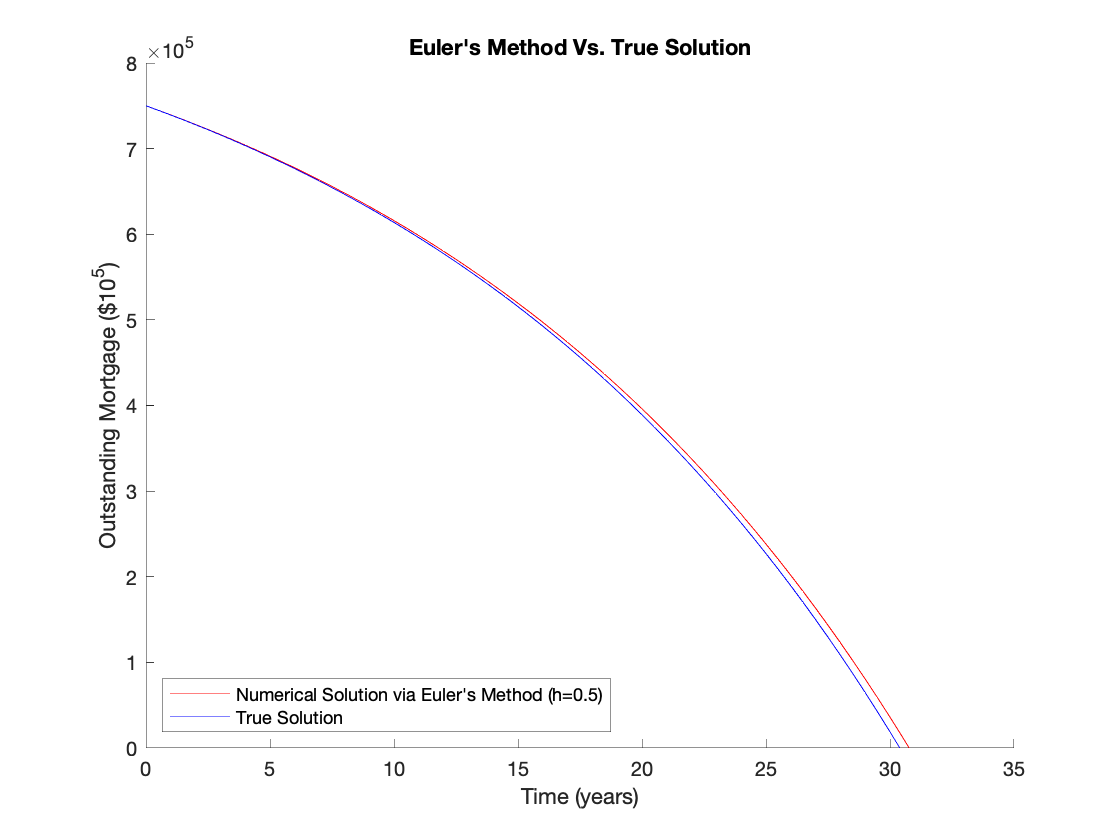

figure;
title("Euler's Method Vs. True Solution")
ts = linspace(0,31,63);
hold on
plot(ts,aprox,'r',ts,960000-210000*exp(0.05.*ts),'b')
legend("Numerical Solution via Euler's Method (h=0.5)","True Solution","location", "southwest")
xlabel("Time (years)")
ylabel("Outstanding Mortgage ($10^5)")
ylim([0 8e5])
hold off